tic;
fnameReadPre = 'rawData/tokyo/';
year = 2020;
fnameReadSuff = 'tokyo_2020/Tokyo_2020';
filename = [fnameReadPre,fnameReadSuff,'.csv']

filename = 'rawData/tokyo_2020/Tokyo_2020.csv'

opts = detectImportOptions(filename);
% data_preview = preview(filename,opts)
data = readtable(filename);
data.Properties.VariableNames = {'time','frequency'};
toc;

fnameWritePre = 'processedData/data_';
fnameWriteSuff = 'tokyo_2020_0';
fnameWrite = [fnameWritePre fnameWriteSuff];
filename = fnameWrite

filename = 'processedData/tokyo_2020'

writetable(data,filename);

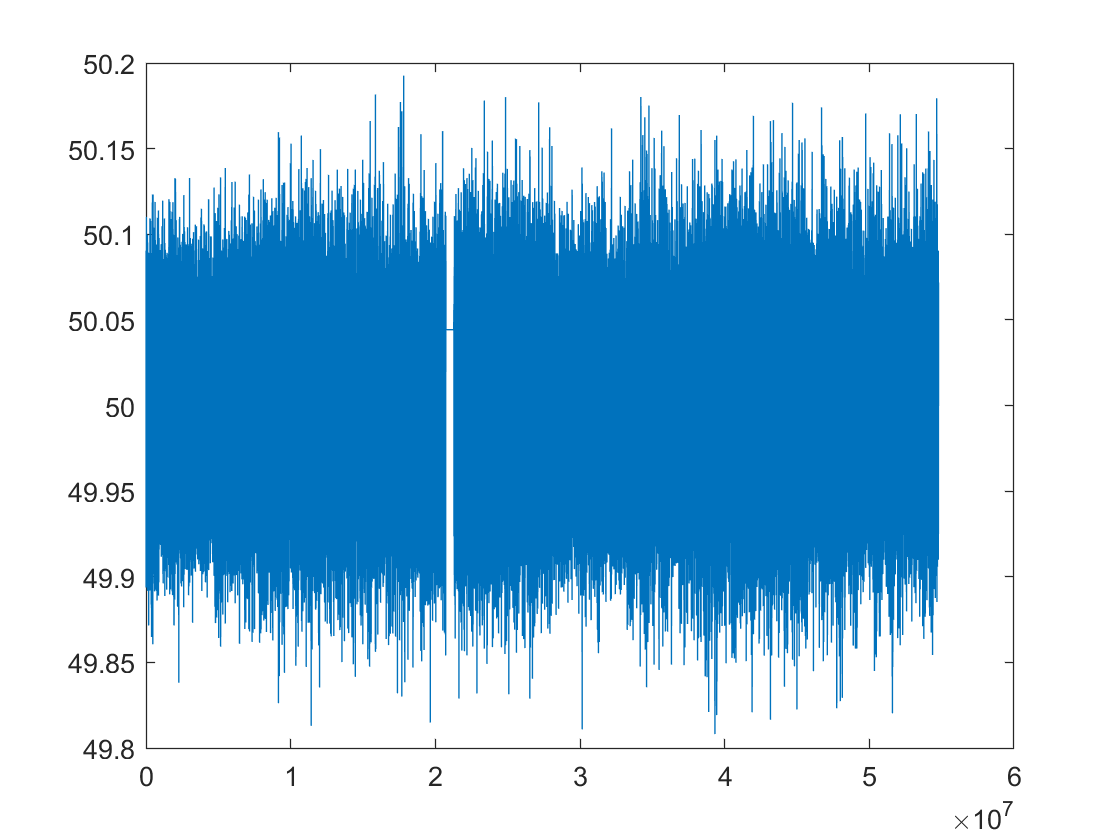

grid = 'tokyo';
[year,month] = selectTimePeriod(grid);
filename = selectInput(grid,year,month,0);
data = readtable(filename);
plot(data.frequency);

#### Lots of spaces in the time stamps in the data. Time to divide the data into smaller pieces with continuous times.

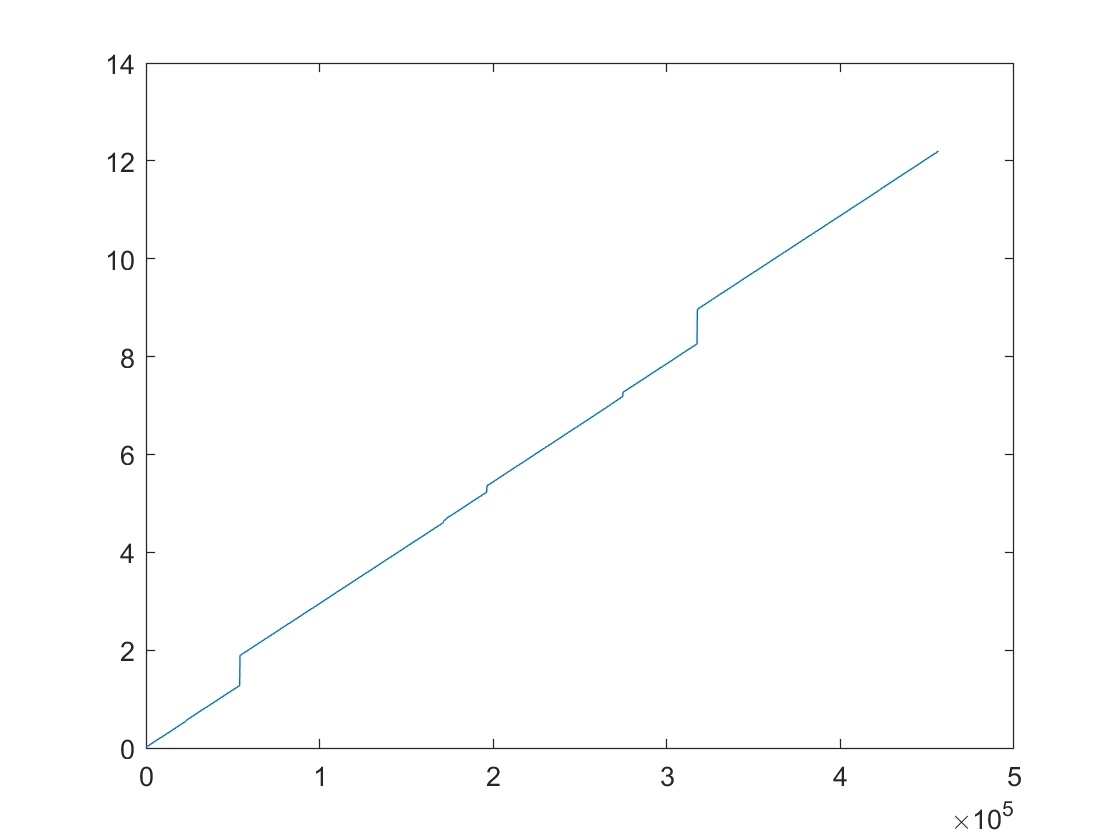

data1 = downsample(data,120); %sample data after every 1 minute
data1.time = data1.time/1000; %convert time from ms to s
%plotting the month timestamp for the data to get an idea for the points of
%to be chosen for dividing the data
plot((data1.time-data1.time(1))/(60*60*24*30)); 


idx = [1];
tic;
for i = 2:length(data1.time)
    %cut across gaps of 1 full day
    %normally there should be a gap of 60 seconds between consecutive
    %entries
    if data1.time(i-1) <= data1.time(i) - 0.5*120*60*24*1
        idx = [idx i];
    end
end
toc;

Elapsed time is 3.829575 seconds.


idx = [idx length(data1.time)];

for i = 1:length(idx)-1
    tic;
    grid = 'tokyo';
    [year,months] = selectTimePeriod(grid);
    month = months(i);
    fnameWritePre = 'processedData/data_';
    if length(num2str(month)) == 1
            strMonth = ['0' num2str(month)];
        else
            strMonth = num2str(month);
    end
    fnameWriteSuff = ['tokyo_2020_' strMonth '_0'];
    fnameWrite = [fnameWritePre fnameWriteSuff];
    filename = fnameWrite
    data2 = data1(idx(i):idx(i+1)-1,:);
    writetable(data2,filename);
    toc;
end

filename = 'processedData/data_tokyo_2020_01_0'

Elapsed time is 0.177442 seconds.


filename = 'processedData/data_tokyo_2020_05_0'

Elapsed time is 0.405742 seconds.


filename = 'processedData/data_tokyo_2020_07_0'

Elapsed time is 0.238386 seconds.


filename = 'processedData/data_tokyo_2020_08_0'

Elapsed time is 0.164695 seconds.


filename = 'processedData/data_tokyo_2020_12_0'

Elapsed time is 0.429042 seconds.
